# data analyse, draw figure

tabel_trim_no_redundant                         = readtable('trim_result_no_redundant.csv');
tabel_trim_redundant_prop                       = readtable('trim_result_redundant_prop.csv');
tabel_trim_redundant_prop_delta_e_min_power     = readtable('trim_redundant_prop_delta_e_min_power.csv');
tabel_trim_redundant_prop_delta_e_power_5load   = readtable('trim_redundant_prop_delta_e_power_5load.csv');
tabel_trim_redundant_prop_var_delta_e_U0        = readtable('trim_redundant_prop_var_delta_e_U0.csv');
tabel_trim_redundant_prop_var_delta_e_U10       = readtable('trim_redundant_prop_var_delta_e_U10.csv');
tabel_trim_redundant_prop_var_delta_e_U20       = readtable('trim_redundant_prop_var_delta_e_U20.csv');
tabel_trim_redundant_prop_var_delta_e_U40       = readtable('trim_redundant_prop_var_delta_e_U30.csv');
tabel_trim_redundant_prop_var_delta_e_U30       = readtable('trim_redundant_prop_var_delta_e_U40.csv');
tabel_trim_redundant_prop_var_delta_e_U45       = readtable('trim_redundant_prop_var_delta_e_U45.csv');
tabel_trim_redundant_prop_var_delta_e_U50       = readtable('trim_redundant_prop_var_delta_e_U50.csv');
tabel_trim_redundant_prop_var_delta_e_U60       = readtable('trim_redundant_prop_var_delta_e_U60.csv');
tabel_trim_redundant_prop_var_delta_e_U71       = readtable('trim_redundant_prop_var_delta_e_U71.csv');
tabel_trim_redundant_prop_var_delta_e_U80       = readtable('trim_redundant_prop_var_delta_e_U80.csv');
tabel_trim_redundant_prop_var_delta_e_U81       = readtable('trim_redundant_prop_var_delta_e_U81.csv');
tabel_trim_redundant_prop_var_delta_e_U100      = readtable('trim_redundant_prop_var_delta_e_U100.csv');

## figure1, x:U, y:power (no redundant, with prop, with delta_e(5%))

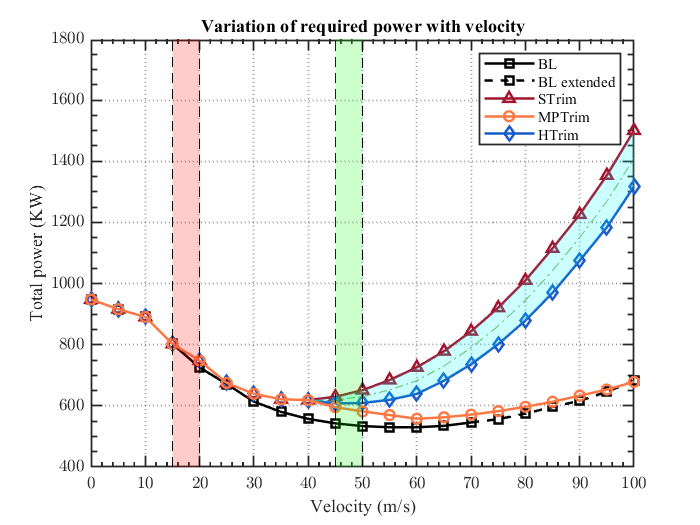

fig = figure;
ax = axes(fig);
%smooth data
x = tabel_trim_no_redundant.U(1:5:71);
y = tabel_trim_no_redundant.power_total(1:5:71)/1000;
y_smooth = smooth(x,y,0.1,'loess');
h1 = plot(ax,x,y_smooth,"LineWidth",1.5,'Color','k','Marker','square');
hold on

x = tabel_trim_no_redundant.U(71:5:end);
y = tabel_trim_no_redundant.power_total(71:5:end)/1000;
h11 = plot(ax,x,y,"LineWidth",1.5,'Color','k','LineStyle','--','Marker',"square");
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = tabel_trim_redundant_prop.power_total(1:5:end)/1000;
y_smooth = smooth(x,y,0.1,'rloess');
data_ub = y_smooth';
h2 = plot(ax,x,y_smooth,"LineWidth",1.5,'Color','#A2142F','Marker','^');
hold on

x = tabel_trim_redundant_prop_delta_e_power_5load.U(1:end);
y = tabel_trim_redundant_prop_delta_e_power_5load.power_total(1:end)/1000;
y_smooth = smooth(x,y);
y_after = [y(1:9);y_smooth(10:end)];
data_lb = y_after';
h4 = plot(ax,x,y_after,"LineWidth",1.5,'Color','#185AC9','Marker','diamond');
hold on

y = (data_ub+data_lb)/2;
plot(x,y,"-.")
hold on

x = tabel_trim_redundant_prop_delta_e_min_power.U(1:end);
y = tabel_trim_redundant_prop_delta_e_min_power.power_total(1:end)/1000;
y_smooth = smooth(x,y);
y_after = [y(1:9);y_smooth(10:end)];
h3 = plot(ax,x,y_after,"LineWidth",1.5,'Color','#FD7844','Marker','o');
hold on

axe = x';
v = [axe' data_lb';axe' data_ub'];
S.Vertices = v;
[number_of_face,~] = size(S.Vertices);
S.Faces = [1:number_of_face/2,number_of_face:-1:number_of_face/2+1];
S.FaceColor = 'cyan';
S.FaceAlpha = 0.2;
%S.EdgeColor = 'black';
S.LineStyle = 'none';
%S.LineWidth = 0.001;
patch(ax,S)
hold on

S.Vertices = [15 0;15 2000;20 2000;20 0];
S.Faces = 1:4;
S.FaceColor = 'red';
S.FaceAlpha = 0.2;
S.EdgeColor = 'black';
S.LineStyle = '--';
S.LineWidth = 0.5;
patch(ax,S)
hold on

S.Vertices = [45 0;45 2000;50 2000;50 0];
S.Faces = 1:4;
S.FaceColor = 'green';
S.FaceAlpha = 0.2;
S.EdgeColor = 'black';
S.LineStyle = '--';
S.LineWidth = 0.5;
patch(S)
hold off

legend([h1,h11,h2,h3,h4],'BL','BL extended','STrim','MPTrim','HTrim');
xlabel('Velocity (m/s)'); ylabel('Total power (KW)');
title('Variation of required power with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;
ax.YLim = [400 1800];

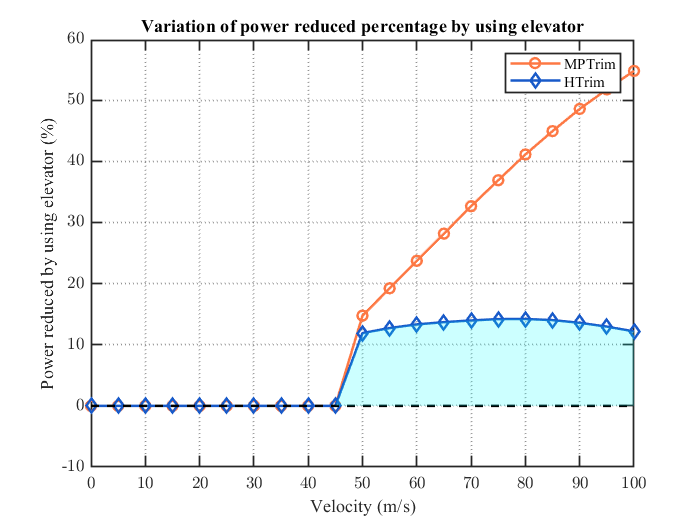


% subplot: decrease percent
fig = figure;
ax = axes(fig);

x = tabel_trim_redundant_prop.U(1:5:end);
y = (tabel_trim_redundant_prop.power_total(1:5:end) - tabel_trim_redundant_prop_delta_e_min_power.power_total)./tabel_trim_redundant_prop.power_total(1:5:end)*100;
y_smooth = smooth(x,y,3);
y_after = [y(1:11);y_smooth(12:end)];
h2 = plot(ax,x,y_after,"LineWidth",1.5,'Color','#FD7844','Marker','o');
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = (tabel_trim_redundant_prop.power_total(1:5:end) - tabel_trim_redundant_prop_delta_e_power_5load.power_total)./tabel_trim_redundant_prop.power_total(1:5:end)*100;
y_smooth = smooth(x,y,3);
y_after = [y(1:11);y_smooth(12:end)];
data_ub = y_after';
h3 = plot(ax,x,y_after,"LineWidth",1.5,'Color','#185AC9','Marker','diamond');
hold on

plot(x,zeros(size(x)),"LineWidth",1.5,'Color','black','LineStyle','--');
data_lb = zeros(size(x))';
hold on

axe = x';
v = [axe' data_lb';axe' data_ub'];
S.Vertices = v;
[number_of_face,~] = size(S.Vertices);
S.Faces = [1:number_of_face/2,number_of_face:-1:number_of_face/2+1];
S.FaceColor = 'cyan';
S.FaceAlpha = 0.2;
S.LineStyle = 'none';
patch(ax,S)
hold off

legend([h2,h3],'MPTrim','HTrim')
xlabel('Velocity (m/s)'); ylabel('Power reduced by using elevator (%)');
title('Variation of power reduced percentage by using elevator');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'off';
ax.YMinorTick = 'off';
ax.TickLength(1) = 0.02;


%ax.YLim = [-5,20];

## Figure2: variation of delta_e X:U, Y: delta_e

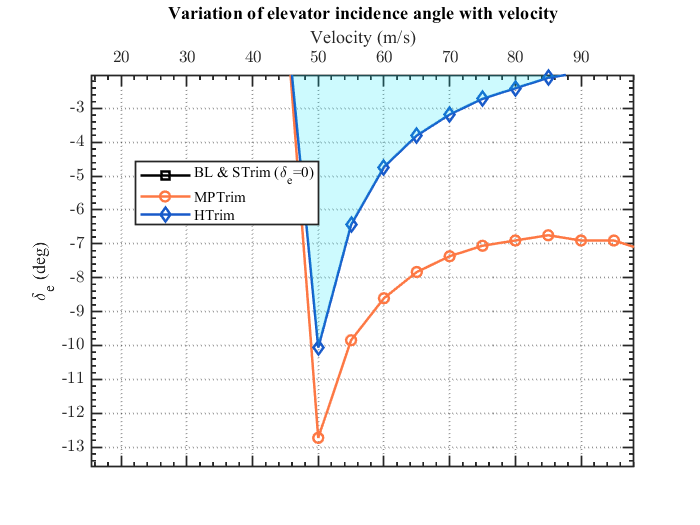

fig = figure;
ax = axes(fig);

x = tabel_trim_redundant_prop.U(1:5:end);
y = rad2deg(tabel_trim_redundant_prop.delta_e(1:5:end));
data_ub1 = y';
plot(x,y,'LineWidth',1.5,"Marker","square",'Color','black')
hold on

x = tabel_trim_redundant_prop_delta_e_min_power.U(1:end);
y = rad2deg(tabel_trim_redundant_prop_delta_e_min_power.delta_e);
%y_after = [];
data_lb2 = y';
plot(x,y,"LineWidth",1.5,"Marker","o",'Color','#FD7844')
hold on

x = tabel_trim_redundant_prop_delta_e_power_5load.U(1:end);
y = rad2deg(tabel_trim_redundant_prop_delta_e_power_5load.delta_e);
data_lb1 = y';
data_ub2 = y';
plot(x,y,"LineWidth",1.5,'Marker',"diamond",'Color','#185AC9')
hold on

axe = x';
v = [axe' data_lb1';axe' data_ub1'];
S.Vertices = v;
[number_of_face,~] = size(S.Vertices);
S.Faces = [1:number_of_face/2,number_of_face:-1:number_of_face/2+1];
S.FaceColor = '#05E4FC';
S.FaceAlpha = 0.2;
S.LineStyle = 'none';
patch(ax,S)
hold on

axe = x';
v = [axe' data_lb2';axe' data_ub2'];
S.Vertices = v;
[number_of_face,~] = size(S.Vertices);
S.Faces = [1:number_of_face/2,number_of_face:-1:number_of_face/2+1];
S.FaceColor = '#EC3418';
S.FaceAlpha = 0.2;
S.LineStyle = 'none';
%patch(ax,S)
hold off

legend('BL & STrim (\delta_e=0)','MPTrim','HTrim');
xlabel('Velocity (m/s)'); ylabel('\delta_e (deg)');
title('Variation of elevator incidence angle with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XAxisLocation = "top";
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;

leg = legend(ax);
leg.Location = 'best';

## figure3a: x:U, y: rotor airload

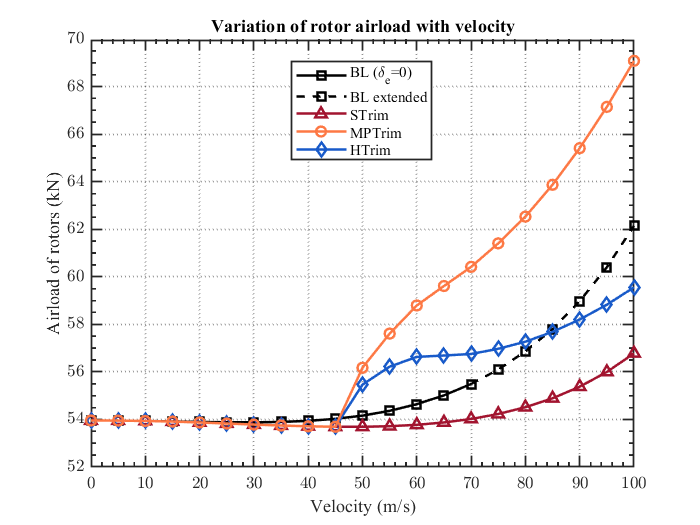

fig = figure;
ax = axes(fig);

x = tabel_trim_no_redundant.U(1:5:71);
y = tabel_trim_no_redundant.T_rotor(1:5:71)/1000;
h0 = plot(ax,x,y,"LineWidth",1.5,'Color','k','Marker',"square");
hold on

x = tabel_trim_no_redundant.U(71:5:end);
y = tabel_trim_no_redundant.T_rotor(71:5:end)/1000;
h00 = plot(ax,x,y,"LineWidth",1.5,'Color','k','LineStyle','--','Marker',"square");
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = tabel_trim_redundant_prop.T_rotor(1:5:end)/1000;
data_lb = y';
h1 = plot(ax,x,y,"LineWidth",1.5,'Color','#A2142F','Marker',"^");
hold on

x = tabel_trim_redundant_prop_delta_e_power_5load.U(1:end);
y = tabel_trim_redundant_prop_delta_e_power_5load.T_rotor(1:end)/1000;
y_smooth = smooth(x,y,0.5,'loess');
y_after = [y(1:10);y_smooth(11:end)];
data_ub = y_after';
h3 = plot(ax,x,y_after,"LineWidth",1.5,'Color','#185AC9','Marker',"diamond");
hold on

x = tabel_trim_redundant_prop_delta_e_min_power.U(1:end);
y = tabel_trim_redundant_prop_delta_e_min_power.T_rotor(1:end)/1000;
y_smooth = smooth(x,y,0.5,'loess');
y_after = [y(1:10);y_smooth(11:end)];
h2 = plot(ax,x,y_after,"LineWidth",1.5,'Color','#FD7844','Marker',"o");
hold on

axe = x';
v = [axe' data_lb';axe' data_ub'];
S.Vertices = v;
[number_of_face,~] = size(S.Vertices);
S.Faces = [1:number_of_face/2,number_of_face:-1:number_of_face/2+1];
S.FaceColor = '#05E4FC';
S.FaceAlpha = 0.2;
S.LineStyle = 'none';
%patch(ax,S)
hold off

legend([h0,h00,h1,h2,h3],'BL (\delta_e=0)','BL extended','STrim','MPTrim','HTrim');
xlabel('Velocity (m/s)'); ylabel('Airload of rotors (kN)');
title('Variation of rotor airload with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;

leg = legend(ax);
leg.Location = 'best';

## Figure 3b x:U, y: propeller thrust

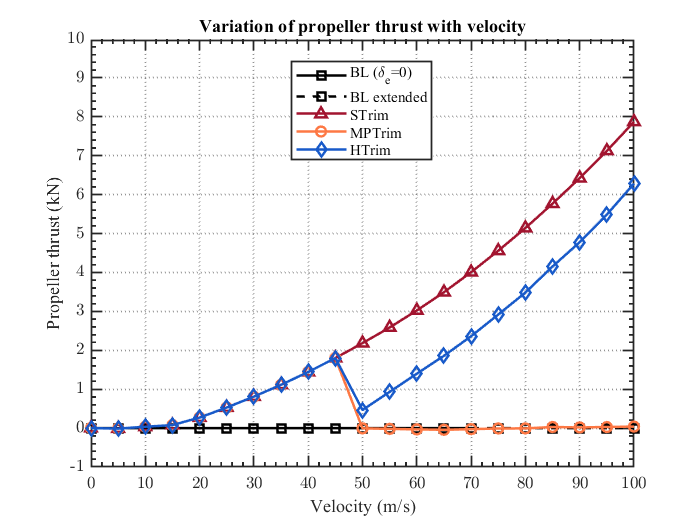

fig = figure;
ax = axes(fig);

x = tabel_trim_no_redundant.U(1:5:71);
y = zeros(size(x));
h0 = plot(ax,x,y,"LineWidth",1.5,'Color','k','Marker',"square");
hold on

x = tabel_trim_no_redundant.U(71:5:end);
y = zeros(size(x));
h00 = plot(ax,x,y,"LineWidth",1.5,'Color','k','LineStyle','--','Marker',"square");
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = tabel_trim_redundant_prop.T_prop(1:5:end)/1000;
data_lb = y';
h1 = plot(ax,x,y,"LineWidth",1.5,'Color','#A2142F','Marker',"^");
hold on

x = tabel_trim_redundant_prop_delta_e_min_power.U(1:end);
y = tabel_trim_redundant_prop_delta_e_min_power.T_prop(1:end)/1000;
y_smooth = smooth(x,y,0.7,'loess');
y_after = [y(1:11);y_smooth(12:end)];
h2 = plot(ax,x,y,"LineWidth",1.5,'Color','#FD7844','Marker',"o");
hold on

x = tabel_trim_redundant_prop_delta_e_power_5load.U(1:end);
y = tabel_trim_redundant_prop_delta_e_power_5load.T_prop(1:end)/1000;
y_smooth = smooth(x,y,0.7,'loess');
y_after = [y(1:10);y_smooth(11:end)];
h3 = plot(ax,x,y,"LineWidth",1.5,'Color','#185AC9','Marker',"diamond");
hold off

legend([h0,h00,h1,h2,h3],'BL (\delta_e=0)','BL extended','STrim','MPTrim','HTrim');
xlabel('Velocity (m/s)'); ylabel('Propeller thrust (kN)');
title('Variation of propeller thrust with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;
ax.YLim = [-1 10];

leg = legend(ax);
leg.Location = 'best';

## Figure4: scatter X:rotor load, Y:total power

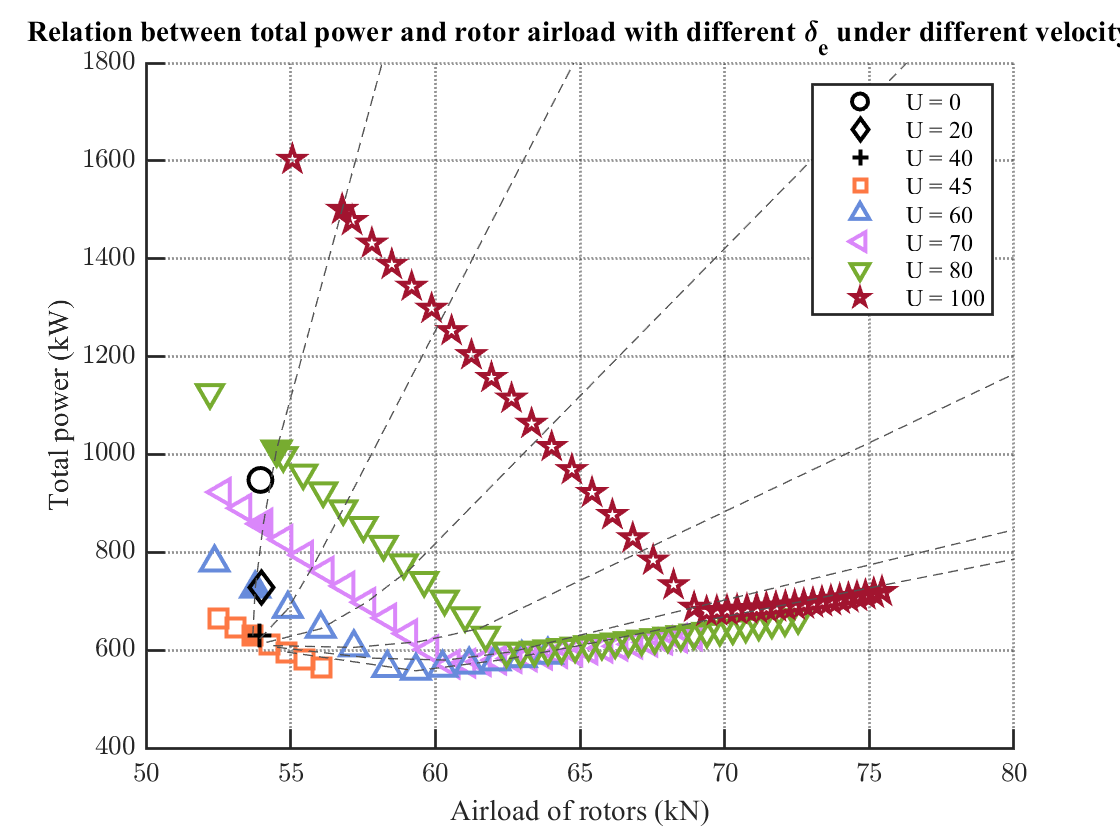

fig = figure;
ax = axes(fig);

h8 = scatter(tabel_trim_redundant_prop_var_delta_e_U71.T_rotor(1:4:end)/1000,tabel_trim_redundant_prop_var_delta_e_U71.power_total(1:4:end)/1000,70);
h8.Marker = "<";
h8.MarkerEdgeColor = '#DA87FA';
h8.LineWidth = 1.5;
h8.MarkerFaceColor = 'none';
hold on
index = tabel_trim_redundant_prop_var_delta_e_U71.delta_e == 0;
h88 = scatter(tabel_trim_redundant_prop_var_delta_e_U71.T_rotor(index)/1000,tabel_trim_redundant_prop_var_delta_e_U71.power_total(index)/1000,80);
h88.Marker = h8.Marker;
h88.MarkerEdgeColor = h8.MarkerEdgeColor;
h88.LineWidth = 1.5;
h88.MarkerFaceColor = h8.MarkerEdgeColor;
hold on

h1 = scatter(tabel_trim_redundant_prop_var_delta_e_U0.T_rotor/1000,tabel_trim_redundant_prop_var_delta_e_U0.power_total/1000,80);
h1.Marker = "o";
h1.MarkerEdgeColor = 'black';
h1.MarkerFaceColor = 'none';
h1.LineWidth = 1.5;
hold on


h4 = scatter(tabel_trim_redundant_prop_var_delta_e_U45.T_rotor(1:25:end)/1000,tabel_trim_redundant_prop_var_delta_e_U45.power_total(1:25:end)/1000,80);
h4.Marker = "square";
h4.MarkerEdgeColor = '#FD7844';
h4.LineWidth = 1.5;
h4.MarkerFaceColor = 'none';
hold on
index = tabel_trim_redundant_prop_var_delta_e_U45.delta_e == 0;
h44 = scatter(tabel_trim_redundant_prop_var_delta_e_U45.T_rotor(index)/1000,tabel_trim_redundant_prop_var_delta_e_U45.power_total(index)/1000,80);
h44.Marker = "square";
h44.MarkerEdgeColor = '#FD7844';
h44.LineWidth = 1.5;
h44.MarkerFaceColor = '#FD7844';
hold on

h3 = scatter(tabel_trim_redundant_prop_var_delta_e_U40.T_rotor(1:500:end)/1000,tabel_trim_redundant_prop_var_delta_e_U40.power_total(1:500:end)/1000,80);
h3.Marker = "+";
h3.MarkerEdgeColor = 'black';
h3.MarkerFaceColor = 'none';
h3.LineWidth = 1.5;
hold on

h5 = scatter(tabel_trim_redundant_prop_var_delta_e_U60.T_rotor(1:10:end)/1000,tabel_trim_redundant_prop_var_delta_e_U60.power_total(1:10:end)/1000,80);
h5.Marker = "^";
h5.MarkerEdgeColor = '#678BDB';
h5.LineWidth = 1.5;
h5.MarkerFaceColor = 'none';
hold on
index = tabel_trim_redundant_prop_var_delta_e_U60.delta_e == 0;
h55 = scatter(tabel_trim_redundant_prop_var_delta_e_U60.T_rotor(index)/1000,tabel_trim_redundant_prop_var_delta_e_U60.power_total(index)/1000,80);
h55.Marker = "^";
h55.MarkerEdgeColor = h5.MarkerEdgeColor;
h55.LineWidth = 1.5;
h55.MarkerFaceColor = h5.MarkerEdgeColor;
hold on

h2 = scatter(tabel_trim_redundant_prop_var_delta_e_U20.T_rotor(1)/1000,tabel_trim_redundant_prop_var_delta_e_U20.power_total(1)/1000,80);
h2.Marker = "diamond";
h2.MarkerEdgeColor = 'black';
h2.MarkerFaceColor = 'none';
h2.LineWidth = 1.5;
hold on

h6 = scatter(tabel_trim_redundant_prop_var_delta_e_U80.T_rotor(1:3:end)/1000,tabel_trim_redundant_prop_var_delta_e_U80.power_total(1:3:end)/1000,70);
h6.Marker = "v";
h6.MarkerEdgeColor = '#77AC30';
h6.LineWidth = 1.5;
h6.MarkerFaceColor = 'none';
hold on
index = tabel_trim_redundant_prop_var_delta_e_U80.delta_e == 0;
h66 = scatter(tabel_trim_redundant_prop_var_delta_e_U80.T_rotor(index)/1000,tabel_trim_redundant_prop_var_delta_e_U80.power_total(index)/1000,80);
h66.Marker = "v";
h66.MarkerEdgeColor = h6.MarkerEdgeColor;
h66.LineWidth = 1.5;
h66.MarkerFaceColor = h6.MarkerEdgeColor;
hold on

h7 = scatter(tabel_trim_redundant_prop_var_delta_e_U100.T_rotor(1:2:end)/1000,tabel_trim_redundant_prop_var_delta_e_U100.power_total(1:2:end)/1000,80);
h7.Marker = "pentagram";
h7.MarkerEdgeColor = '#A2142F';
h7.LineWidth = 1.5;
h7.MarkerFaceColor = 'none';
hold on
index = tabel_trim_redundant_prop_var_delta_e_U100.delta_e == 0;
h77 = scatter(tabel_trim_redundant_prop_var_delta_e_U100.T_rotor(index)/1000,tabel_trim_redundant_prop_var_delta_e_U100.power_total(index)/1000,80);
h77.Marker = "pentagram";
h77.MarkerEdgeColor = h7.MarkerEdgeColor;
h77.LineWidth = 1.5;
h77.MarkerFaceColor = h7.MarkerEdgeColor;
hold on

% manual contour
cell_data = {tabel_trim_redundant_prop_var_delta_e_U45,tabel_trim_redundant_prop_var_delta_e_U60,tabel_trim_redundant_prop_var_delta_e_U71,tabel_trim_redundant_prop_var_delta_e_U80,tabel_trim_redundant_prop_var_delta_e_U100};
number_cell_data = length(cell_data);
array_target = deg2rad([-10 -7 -6 -4 -2 0 1]);
number_target = length(array_target);

x = zeros(number_target,number_cell_data);
y = zeros(number_target,number_cell_data);
x_max = 100;

for k = 1:number_target
    ele_target = array_target(k);
    for m = 1:number_cell_data
        ele_data = cell_data{m};
        
        array_residual = abs(ele_data.delta_e - ele_target);
        index = array_residual == min(array_residual);
        x(k,m) = ele_data.T_rotor(index)/1000;
        y(k,m) = ele_data.power_total(index)/1000;
    end
end

for k = 1:number_target-1
    f=fit(x(k,:)',y(k,:)','linear');
    plot([x(k,:),x_max],f([x(k,:),x_max]),'Color','#525252','LineStyle','--' );
    %plot(x(k,:),y(k,:),'Color','#8A8A8A','LineStyle','--')
    hold on
end
hold off


legend([h1,h2,h3,h4,h5,h8,h6,h7],'U = 0','U = 20','U = 40','U = 45','U = 60','U = 70','U = 80','U = 100');
xlabel('Airload of rotors (kN)'); ylabel('Total power (kW)');
title('Relation between total power and rotor airload with different \delta_e under different velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'off';
ax.YMinorTick = 'off';
ax.TickLength(1) = 0.02;
ax.YLim = [400,1800];
ax.XLim = [50,80];


%leg = legend(ax);
%leg.Location = 'best';


## try manual contour

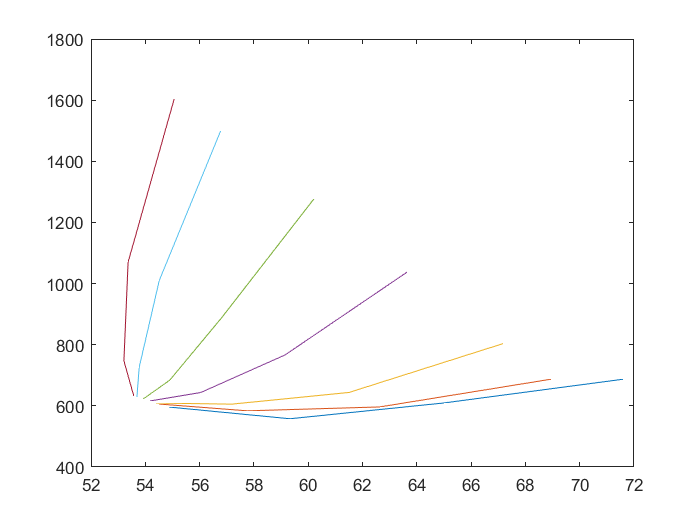

cell_data = {tabel_trim_redundant_prop_var_delta_e_U45,tabel_trim_redundant_prop_var_delta_e_U60,tabel_trim_redundant_prop_var_delta_e_U80,tabel_trim_redundant_prop_var_delta_e_U100};
number_cell_data = length(cell_data);
array_target = deg2rad([-10 -7 -6 -4 -2 0 1]);
number_target = length(array_target);
number_axe = number_target*number_cell_data;

x = zeros(number_target,number_cell_data);
y = zeros(number_target,number_cell_data);

for k = 1:number_target
    ele_target = array_target(k);
    for m = 1:number_cell_data
        ele_data = cell_data{m};
        
        array_residual = abs(ele_data.delta_e - ele_target);
        index = array_residual == min(array_residual);
        x(k,m) = ele_data.T_rotor(index)/1000;
        y(k,m) = ele_data.power_total(index)/1000;
    end
end

for k = 1:number_target
    plot(x(k,:),y(k,:))
    hold on
end
hold off

## Figure: theta_0 X:v y:theta_0 (no ele, ele)

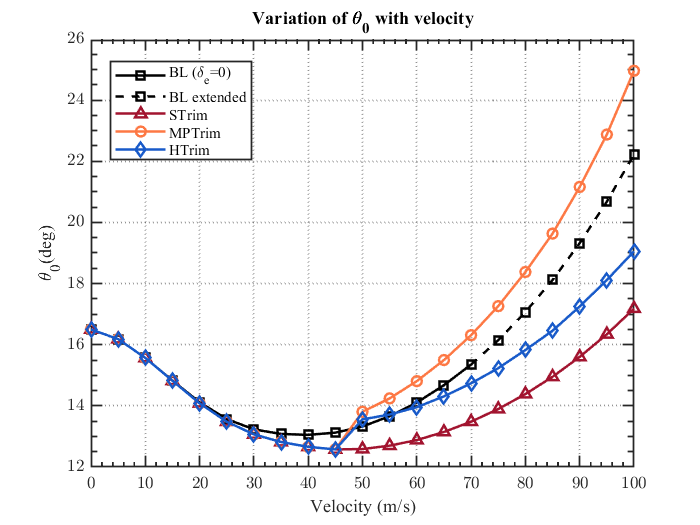

fig = figure;
ax = axes(fig);

x = tabel_trim_no_redundant.U(1:5:71);
y = rad2deg(tabel_trim_no_redundant.theta_0(1:5:71));
h0 = plot(ax,x,y,"LineWidth",1.5,'Color','k','Marker','square');
hold on

x = tabel_trim_no_redundant.U(71:5:end);
y = rad2deg(tabel_trim_no_redundant.theta_0(71:5:end));
h00 = plot(ax,x,y,"LineWidth",1.5,'Color','k','LineStyle','--','Marker',"square");
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = rad2deg(tabel_trim_redundant_prop.theta_0(1:5:end));
h1 = plot(ax,x,y,"LineWidth",1.5,'Color','#A2142F','Marker','^');
hold on

x = tabel_trim_redundant_prop_delta_e_min_power.U;
y = rad2deg(tabel_trim_redundant_prop_delta_e_min_power.theta_0);
y_smooth = smooth(x,y);
y_after = [y(1:10);y_smooth(11:end)];
h2 = plot(ax,x,y,"LineWidth",1.5,'Color','#FD7844','Marker',"o");
hold on

x = tabel_trim_redundant_prop_delta_e_power_5load.U;
y = rad2deg(tabel_trim_redundant_prop_delta_e_power_5load.theta_0);
y_smooth = smooth(x,y);
y_after = [y(1:10);y_smooth(11:end)];
h3 = plot(ax,x,y,"LineWidth",1.5,'Color','#185AC9','Marker','diamond');
hold off

legend([h0,h00,h1,h2,h3],'BL (\delta_e=0)','BL extended','STrim','MPTrim','HTrim');
xlabel('Velocity (m/s)'); ylabel('\theta_0(deg)');
title('Variation of \theta_0 with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;

leg = legend(ax);
leg.Location = 'best';

## figure theta_1c X:v y:theta_1c (no ele, ele)

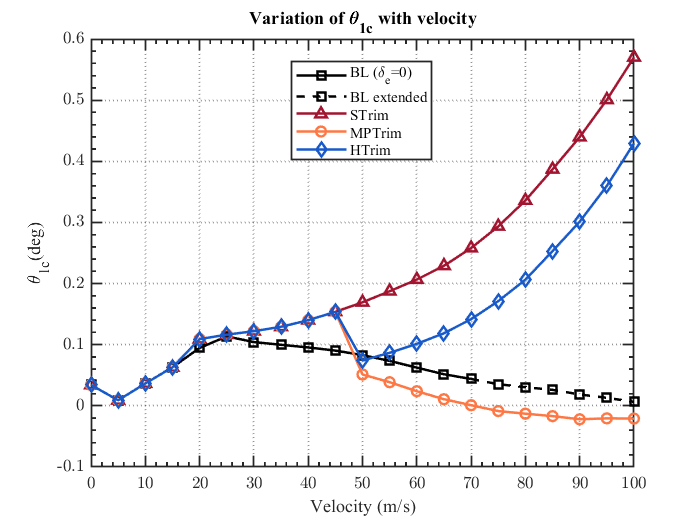

fig = figure;
ax = axes(fig);

x = tabel_trim_no_redundant.U(1:5:71);
y = rad2deg(tabel_trim_no_redundant.theta_1c(1:5:71));
h0 = plot(ax,x,y,"LineWidth",1.5,'Color','k','Marker','square');
hold on

x = tabel_trim_no_redundant.U(71:5:end);
y = rad2deg(tabel_trim_no_redundant.theta_1c(71:5:end));
h00 = plot(ax,x,y,"LineWidth",1.5,'Color','k','LineStyle','--','Marker',"square");
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = rad2deg(tabel_trim_redundant_prop.theta_1c(1:5:end));
h1 = plot(ax,x,y,"LineWidth",1.5,'Color','#A2142F','Marker','^');
hold on

x = tabel_trim_redundant_prop_delta_e_min_power.U;
y = rad2deg(tabel_trim_redundant_prop_delta_e_min_power.theta_1c);
y_smooth = smooth(x,y);
y_after = [y(1:10);y_smooth(11:end)];
h2 = plot(ax,x,y,"LineWidth",1.5,'Color','#FD7844','Marker',"o");
hold on

x = tabel_trim_redundant_prop_delta_e_power_5load.U;
y = rad2deg(tabel_trim_redundant_prop_delta_e_power_5load.theta_1c);
y_smooth = smooth(x,y);
y_after = [y(1:10);y_smooth(11:end)];
h3 = plot(ax,x,y,"LineWidth",1.5,'Color','#185AC9','Marker','diamond');
hold off

legend([h0,h00,h1,h2,h3],'BL (\delta_e=0)','BL extended','STrim','MPTrim','HTrim');
xlabel('Velocity (m/s)'); ylabel('\theta_{1c}(deg)');
title('Variation of \theta_{1c} with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;

leg = legend(ax);
leg.Location = 'best';

## figure theta_1s X:v y:theta_1s (no ele, ele)

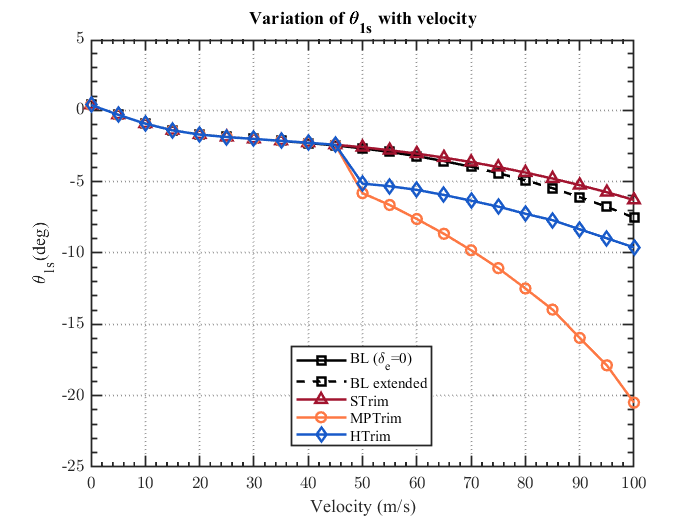

fig = figure;
ax = axes(fig);

x = tabel_trim_no_redundant.U(1:5:71);
y = rad2deg(tabel_trim_no_redundant.theta_1s(1:5:71));
h0 = plot(ax,x,y,"LineWidth",1.5,'Color','k','Marker','square');
hold on

x = tabel_trim_no_redundant.U(71:5:end);
y = rad2deg(tabel_trim_no_redundant.theta_1s(71:5:end));
h00 = plot(ax,x,y,"LineWidth",1.5,'Color','k','LineStyle','--','Marker',"square");
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = rad2deg(tabel_trim_redundant_prop.theta_1s(1:5:end));
h1 = plot(ax,x,y,"LineWidth",1.5,'Color','#A2142F','Marker','^');
hold on

x = tabel_trim_redundant_prop_delta_e_min_power.U;
y = rad2deg(tabel_trim_redundant_prop_delta_e_min_power.theta_1s);
y_smooth = smooth(x,y);
y_after = [y(1:10);y_smooth(11:end)];
h2 = plot(ax,x,y,"LineWidth",1.5,'Color','#FD7844','Marker',"o");
hold on

x = tabel_trim_redundant_prop_delta_e_power_5load.U;
y = rad2deg(tabel_trim_redundant_prop_delta_e_power_5load.theta_1s);
y_smooth = smooth(x,y);
y_after = [y(1:10);y_smooth(11:end)];
h3 = plot(ax,x,y,"LineWidth",1.5,'Color','#185AC9','Marker','diamond');
hold off

legend([h0,h00,h1,h2,h3],'BL (\delta_e=0)','BL extended','STrim','MPTrim','HTrim');
xlabel('Velocity (m/s)'); ylabel('\theta_{1s}(deg)');
title('Variation of \theta_{1s} with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;

leg = legend(ax);
leg.Location = 'best';

## figure theta_diff X:v y:theta_diff (no ele, ele)

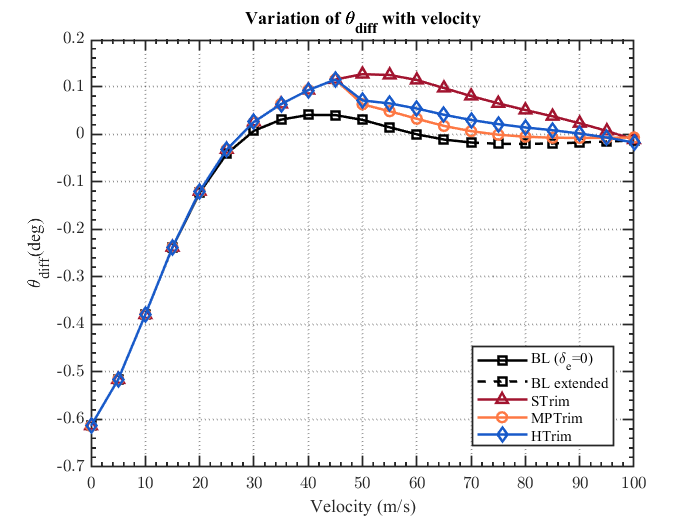

fig = figure;
ax = axes(fig);

x = tabel_trim_no_redundant.U(1:5:71);
y = rad2deg(tabel_trim_no_redundant.theta_diff(1:5:71));
h0 = plot(ax,x,y,"LineWidth",1.5,'Color','k','Marker','square');
hold on

x = tabel_trim_no_redundant.U(71:5:end);
y = rad2deg(tabel_trim_no_redundant.theta_diff(71:5:end));
h00 = plot(ax,x,y,"LineWidth",1.5,'Color','k','LineStyle','--','Marker',"square");
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = rad2deg(tabel_trim_redundant_prop.theta_diff(1:5:end));
h1 = plot(ax,x,y,"LineWidth",1.5,'Color','#A2142F','Marker','^');
hold on

x = tabel_trim_redundant_prop_delta_e_min_power.U;
y = rad2deg(tabel_trim_redundant_prop_delta_e_min_power.theta_diff);
y_smooth = smooth(x,y);
y_after = [y(1:10);y_smooth(11:end)];
h2 = plot(ax,x,y,"LineWidth",1.5,'Color','#FD7844','Marker',"o");
hold on

x = tabel_trim_redundant_prop_delta_e_power_5load.U;
y = rad2deg(tabel_trim_redundant_prop_delta_e_power_5load.theta_diff);
y_smooth = smooth(x,y);
y_after = [y(1:10);y_smooth(11:end)];
h3 = plot(ax,x,y,"LineWidth",1.5,'Color','#185AC9','Marker','diamond');
hold off

legend([h0,h00,h1,h2,h3],'BL (\delta_e=0)','BL extended','STrim','MPTrim','HTrim');
xlabel('Velocity (m/s)'); ylabel('\theta_{diff}(deg)');
title('Variation of \theta_{diff} with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;

leg = legend(ax);
leg.Location = 'best';

## x:U,y:phi

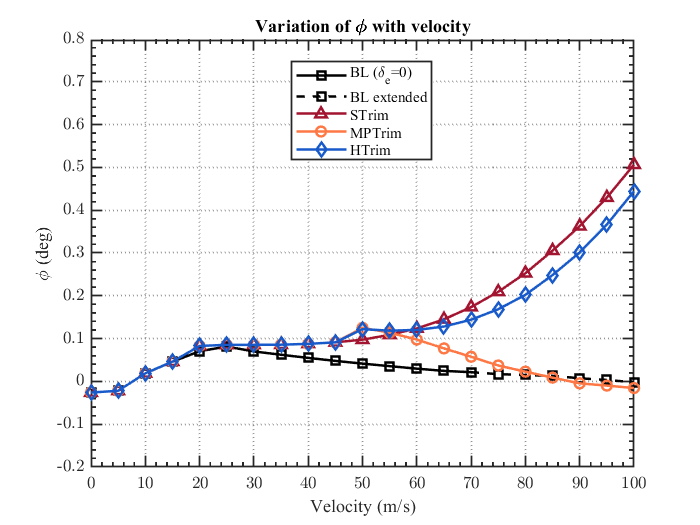

fig = figure;
ax = axes(fig);

x = tabel_trim_no_redundant.U(1:5:71);
y = rad2deg(tabel_trim_no_redundant.phi(1:5:71));
h0 = plot(ax,x,y,"LineWidth",1.5,'Color','k','Marker','square');
hold on

x = tabel_trim_no_redundant.U(71:5:end);
y = rad2deg(tabel_trim_no_redundant.phi(71:5:end));
h00 = plot(ax,x,y,"LineWidth",1.5,'Color','k','LineStyle','--','Marker',"square");
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = rad2deg(tabel_trim_redundant_prop.phi(1:5:end));
h1 = plot(ax,x,y,"LineWidth",1.5,'Color','#A2142F','Marker','^');
hold on

x = tabel_trim_redundant_prop_delta_e_min_power.U;
y = rad2deg(tabel_trim_redundant_prop_delta_e_min_power.phi);
y_smooth = smooth(x,y);
y_after = [y(1:10);y_smooth(11:end)];
h2 = plot(ax,x,y,"LineWidth",1.5,'Color','#FD7844','Marker',"o");
hold on

x = tabel_trim_redundant_prop_delta_e_power_5load.U;
y = rad2deg(tabel_trim_redundant_prop_delta_e_power_5load.phi);
y_smooth = smooth(x,y);
y_after = [y(1:10);y_smooth(11:end)];
h3 = plot(ax,x,y,"LineWidth",1.5,'Color','#185AC9','Marker','diamond');
hold off

legend([h0,h00,h1,h2,h3],'BL (\delta_e=0)','BL extended','STrim','MPTrim','HTrim');
xlabel('Velocity (m/s)'); ylabel('\phi (deg)');
title('Variation of \phi with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;
ax.YLim = [-0.2,0.8];

leg = legend(ax);
leg.Location = 'best';

## x:U, y:theta

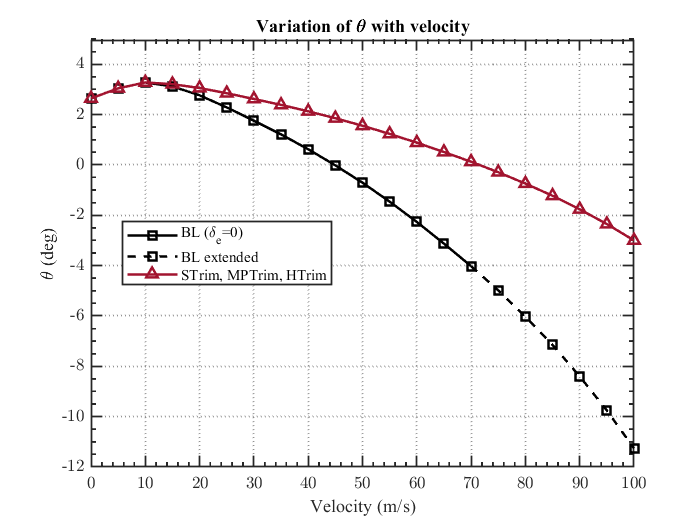

fig = figure;
ax = axes(fig);

x = tabel_trim_no_redundant.U(1:5:71);
y = rad2deg(tabel_trim_no_redundant.theta(1:5:71));
h0 = plot(ax,x,y,"LineWidth",1.5,'Color','k','Marker','square');
hold on

x = tabel_trim_no_redundant.U(71:5:end);
y = rad2deg(tabel_trim_no_redundant.theta(71:5:end));
h00 = plot(ax,x,y,"LineWidth",1.5,'Color','k','LineStyle','--','Marker',"square");
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = rad2deg(tabel_trim_redundant_prop.theta(1:5:end));
h1 = plot(ax,x,y,"LineWidth",1.5,'Color','#A2142F','Marker','^');
hold off

legend([h0,h00,h1],'BL (\delta_e=0)','BL extended','STrim, MPTrim, HTrim');
xlabel('Velocity (m/s)'); ylabel('\theta (deg)');
title('Variation of \theta with velocity');

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.5;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;
ax.YLim = [-12,5];

leg = legend(ax);
leg.Location = 'best';

theta preconfig

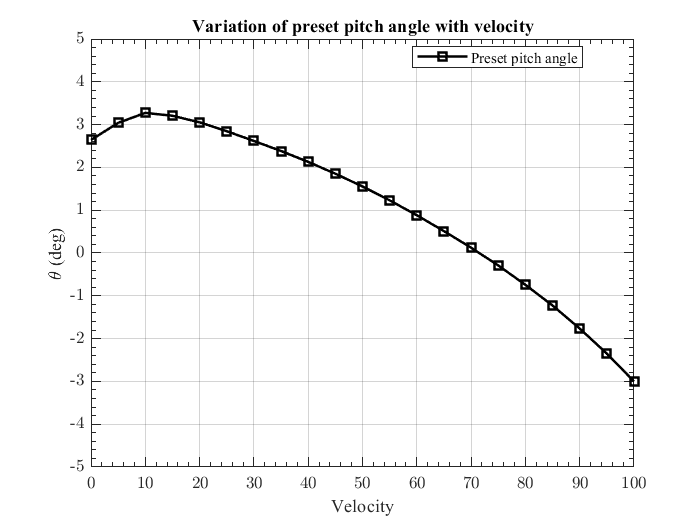

fig = figure;
ax = axes(fig);

x = tabel_trim_redundant_prop.U(1:5:end);
y = rad2deg(tabel_trim_redundant_prop.theta(1:5:end));
h1 = plot(x,y,'k','LineWidth',1.5,'Marker','square');
legend('Preset pitch angle');
xlabel('Velocity (m/s)');ylabel('\theta (deg)'); title('Variation of preset pitch angle with velocity')

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = "-";
ax.GridAlpha = 0.2;
ax.LineWidth = 0.5;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;
ax.YLim = [-5,5];

leg = legend(ax);
leg.Location = 'best';

## Moment and force analyse

% create data
matrix_rotor1   = zeros(4,3);
matrix_rotor2   = zeros(4,3);
matrix_prop    = zeros(4,3);
matrix_elevator = zeros(4,3);
table_config0 = tabel_trim_no_redundant;
table_config1 = tabel_trim_redundant_prop

table_config1 = 101×30 table
    U     theta_0    theta_diff     theta_1c      theta_1s       theta          phi         v_i1      v_i2     v_iprop     Prop_theta_0    Prop_isEnable    delta_e    delta_r    theta_1c_diff    theta_1s_diff     v_01      v_02     beta_01      beta_1c1      beta_1s1     beta_02      beta_1c2      beta_1s2     power_total_LowerRotor    power_total_UpperRotor    power_total_Prop    power_total     T_prop     T_rotor
    __    _______

table_config2 = tabel_trim_redundant_prop_delta_e_min_power;
table_config3 = tabel_trim_redundant_prop_delta_e_power_5load;
U = 70;

table_slice_config0 =   table_config0(table_config0.U == U,:);
[~,Rotorcraft_config0,~] = calculate_from_trim_table(table_slice_config0);

matrix_rotor1(1,1) = Rotorcraft_config0.LowerRotor.X;
matrix_rotor1(1,2) = Rotorcraft_config0.LowerRotor.Z;
matrix_rotor1(1,3) = Rotorcraft_config0.LowerRotor.M;

matrix_rotor2(1,1) = Rotorcraft_config0.UpperRotor.X;
matrix_rotor2(1,2) = Rotorcraft_config0.UpperRotor.Z;
matrix_rotor2(1,3) = Rotorcraft_config0.UpperRotor.M;

matrix_prop(1,1) = Rotorcraft_config0.Prop.X;
matrix_prop(1,2) = Rotorcraft_config0.Prop.Z;
matrix_prop(1,3) = Rotorcraft_config0.Prop.M;

matrix_elevator(1,1) = Rotorcraft_config0.HorStab.X;
matrix_elevator(1,2) = Rotorcraft_config0.HorStab.Z;
matrix_elevator(1,3) = Rotorcraft_config0.HorStab.M;


table_slice_config1 =   table_config1(table_config1.U == U,:);
[~,Rotorcraft_config1,~] = calculate_from_trim_table(table_slice_config1);

matrix_rotor1(2,1) = Rotorcraft_config1.LowerRotor.X;
matrix_rotor1(2,2) = Rotorcraft_config1.LowerRotor.Z;
matrix_rotor1(2,3) = Rotorcraft_config1.LowerRotor.M;

matrix_rotor2(2,1) = Rotorcraft_config1.UpperRotor.X;
matrix_rotor2(2,2) = Rotorcraft_config1.UpperRotor.Z;
matrix_rotor2(2,3) = Rotorcraft_config1.UpperRotor.M;

matrix_prop(2,1) = Rotorcraft_config1.Prop.X;
matrix_prop(2,2) = Rotorcraft_config1.Prop.Z;
matrix_prop(2,3) = Rotorcraft_config1.Prop.M;

matrix_elevator(2,1) = Rotorcraft_config1.HorStab.X;
matrix_elevator(2,2) = Rotorcraft_config1.HorStab.Z;
matrix_elevator(2,3) = Rotorcraft_config1.HorStab.M;

table_slice_config2 =   table_config2(table_config2.U == U,:);
[~,Rotorcraft_config2,~] = calculate_from_trim_table(table_slice_config2);

matrix_rotor1(3,1) = Rotorcraft_config2.LowerRotor.X;
matrix_rotor1(3,2) = Rotorcraft_config2.LowerRotor.Z;
matrix_rotor1(3,3) = Rotorcraft_config2.LowerRotor.M;

matrix_rotor2(3,1) = Rotorcraft_config2.UpperRotor.X;
matrix_rotor2(3,2) = Rotorcraft_config2.UpperRotor.Z;
matrix_rotor2(3,3) = Rotorcraft_config2.UpperRotor.M;

matrix_prop(3,1) = Rotorcraft_config2.Prop.X;
matrix_prop(3,2) = Rotorcraft_config2.Prop.Z;
matrix_prop(3,3) = Rotorcraft_config2.Prop.M;

matrix_elevator(3,1) = Rotorcraft_config2.HorStab.X;
matrix_elevator(3,2) = Rotorcraft_config2.HorStab.Z;
matrix_elevator(3,3) = Rotorcraft_config2.HorStab.M;

table_slice_config3 =   table_config3(table_config3.U == U,:);
[~,Rotorcraft_config3,~] = calculate_from_trim_table(table_slice_config3);

matrix_rotor1(4,1) = Rotorcraft_config3.LowerRotor.X;
matrix_rotor1(4,2) = Rotorcraft_config3.LowerRotor.Z;
matrix_rotor1(4,3) = Rotorcraft_config3.LowerRotor.M;

matrix_rotor2(4,1) = Rotorcraft_config3.UpperRotor.X;
matrix_rotor2(4,2) = Rotorcraft_config3.UpperRotor.Z;
matrix_rotor2(4,3) = Rotorcraft_config3.UpperRotor.M;

matrix_prop(4,1) = Rotorcraft_config3.Prop.X;
matrix_prop(4,2) = Rotorcraft_config3.Prop.Z;
matrix_prop(4,3) = Rotorcraft_config3.Prop.M;

matrix_elevator(4,1) = Rotorcraft_config3.HorStab.X;
matrix_elevator(4,2) = Rotorcraft_config3.HorStab.Z;
matrix_elevator(4,3) = Rotorcraft_config3.HorStab.M;

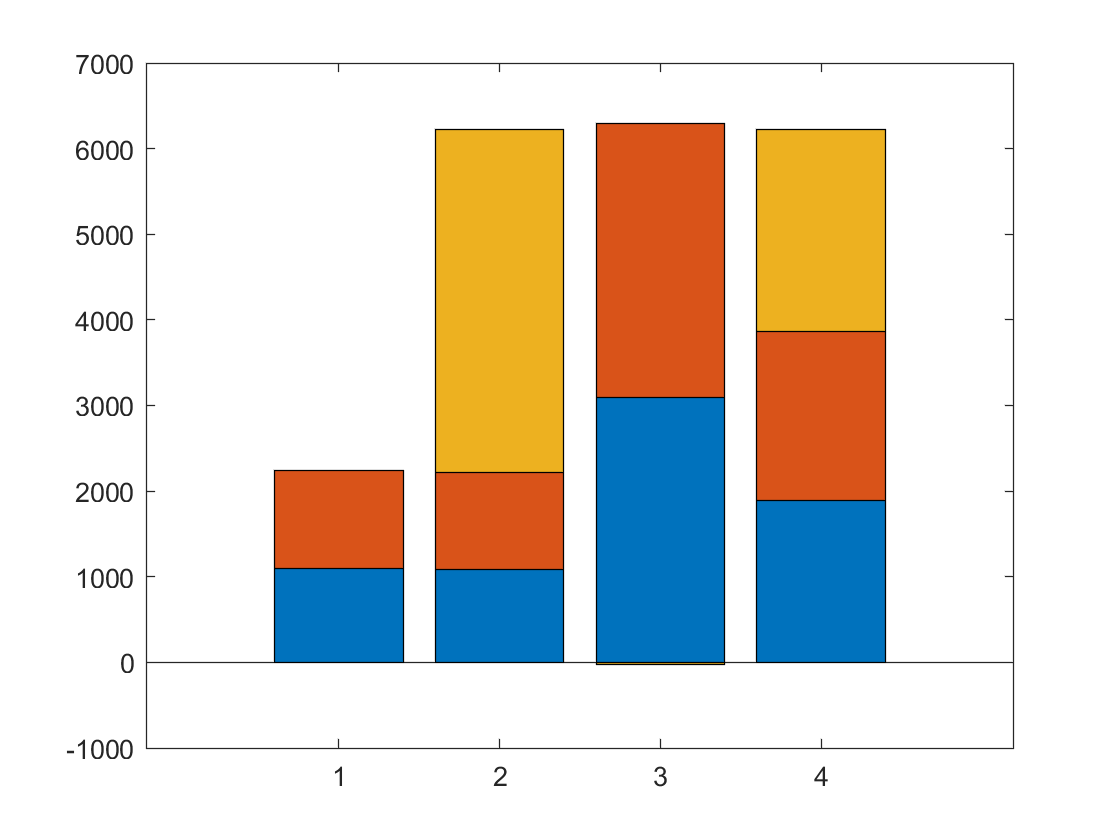

% draw
data_X = [matrix_rotor1(1,1),matrix_rotor2(1,1),matrix_prop(1,1);
    matrix_rotor1(2,1),matrix_rotor2(2,1),matrix_prop(2,1);
    matrix_rotor1(3,1),matrix_rotor2(3,1),matrix_prop(3,1);
    matrix_rotor1(4,1),matrix_rotor2(4,1),matrix_prop(4,1)];
b_X = bar(data_X,'stacked');

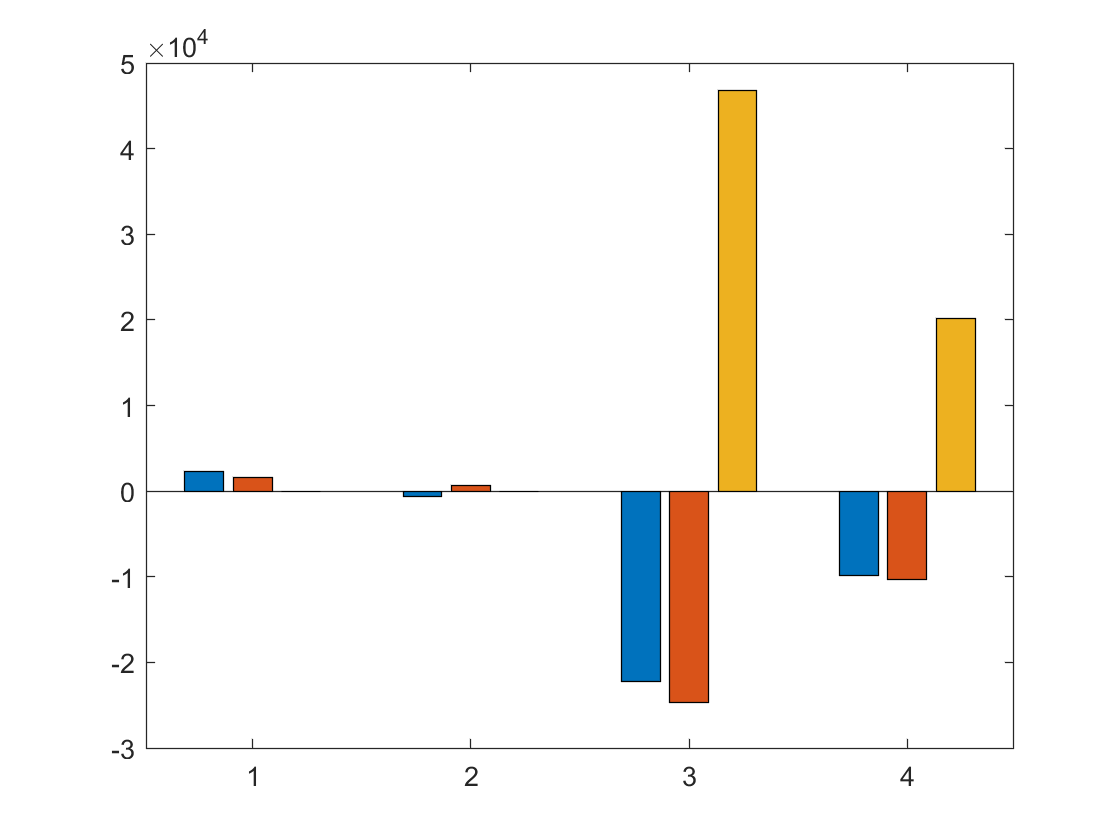


% data_Z = [matrix_rotor1(1,2),matrix_elevator(1,2);
%     matrix_rotor1(2,2),matrix_elevator(2,2);
%     matrix_rotor1(3,2),matrix_elevator(3,2)];
% b_Z = bar(data_Z);

data_M = [matrix_rotor1(1,3),matrix_rotor2(1,3),matrix_elevator(1,3);
    matrix_rotor1(2,3),matrix_rotor2(2,3),matrix_elevator(2,3);
    matrix_rotor1(3,3),matrix_rotor2(3,3),matrix_elevator(3,3);
    matrix_rotor1(4,3),matrix_rotor2(4,3),matrix_elevator(4,3)];
b_M = bar(data_M);

## 升降舵受力 另一种画法

table_use = tabel_trim_redundant_prop_var_delta_e_U71;
array_delta_e = table_use.delta_e;
number_delta_e = length(array_delta_e);
array_rotor1_X = zeros(size(array_delta_e));
array_rotor1_Z = zeros(size(array_delta_e));
array_rotor1_M = zeros(size(array_delta_e));
array_rotor1_L = zeros(size(array_delta_e));

array_rotor2_X = zeros(size(array_delta_e));
array_rotor2_Z = zeros(size(array_delta_e));
array_rotor2_M = zeros(size(array_delta_e));
array_rotor2_L = zeros(size(array_delta_e));

array_prop_X = zeros(size(array_delta_e));
array_prop_L = zeros(size(array_delta_e));

array_delta_e_M = zeros(size(array_delta_e));
array_delta_e_Z = zeros(size(array_delta_e));

for k = 1:number_delta_e
    table_slice = table_use(k,:);
    [x_trim,Rotorcraft,~] = calculate_from_trim_table(table_slice);
    array_rotor1_X(k) = Rotorcraft.LowerRotor.X;
    array_rotor1_Z(k) = Rotorcraft.LowerRotor.Z;
    array_rotor1_M(k) = Rotorcraft.LowerRotor.M;
    array_rotor1_L(k) = Rotorcraft.LowerRotor.L;
    
    array_rotor2_X(k) = Rotorcraft.UpperRotor.X;
    array_rotor2_Z(k) = Rotorcraft.UpperRotor.Z;
    array_rotor2_M(k) = Rotorcraft.UpperRotor.M;
    array_rotor2_L(k) = Rotorcraft.UpperRotor.L;
    
    array_prop_X(k) = Rotorcraft.Prop.X;
    array_prop_L(k) = Rotorcraft.Prop.L;
    
    array_delta_e_M(k) = Rotorcraft.HorStab.M;
    array_delta_e_Z(k) = Rotorcraft.HorStab.Z;
end


## draw

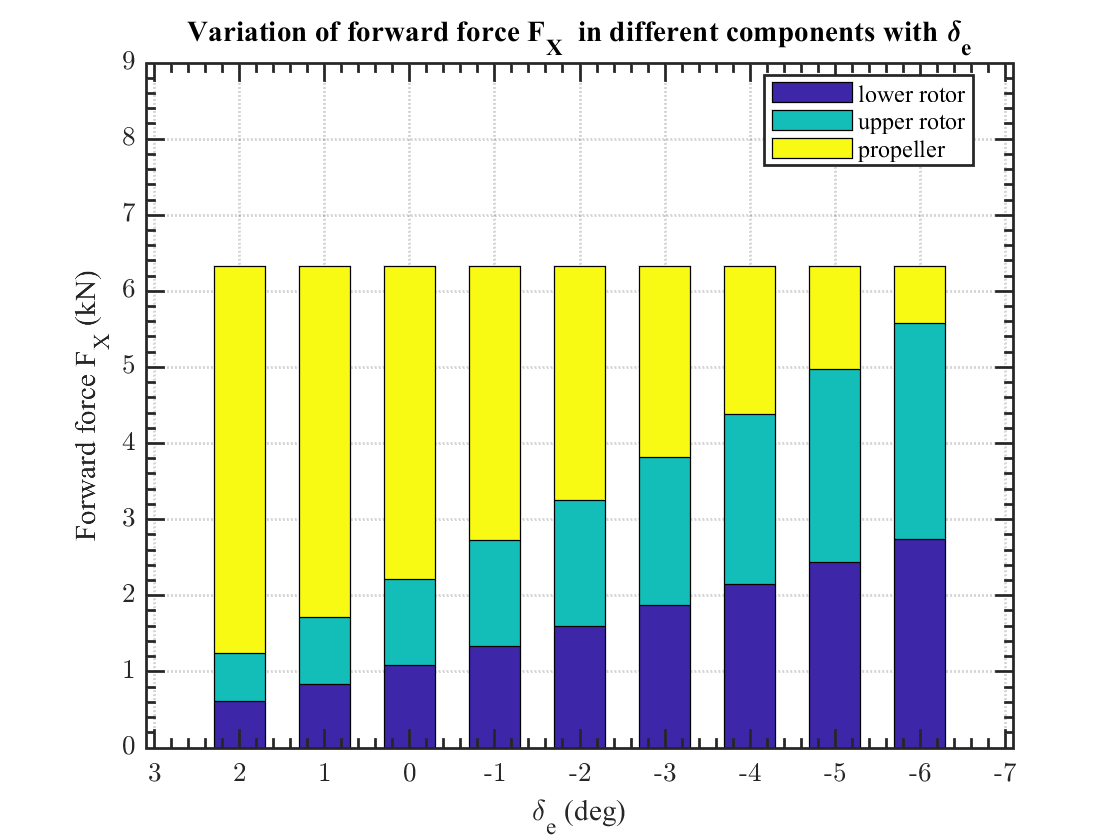

% X
fig = figure;
ax = axes(fig);

x = rad2deg(array_delta_e);
y1 = array_rotor1_X;
y2 = array_rotor2_X;
y3 = array_prop_X;

x = x(71:5:end);
y1 = y1(71:5:end)/1000;
y2 = y2(71:5:end)/1000;
y3 = y3(71:5:end)/1000;

x = flip(x);
y1 = flip(y1);
y2 = flip(y2);
y3 = flip(y3);

Y = [y1,y2,y3];
b1 = bar(x,Y,'stacked','BarWidth',0.6,'FaceColor','flat');
set(gca,'XDir','reverse')
for k = 1:size(Y,2)
    b1(k).CData = k;
end

legend('lower rotor','upper rotor','propeller')
xlabel('\delta_e (deg)');ylabel('Forward force F_X (kN)');
title(['Variation of forward force F_X ' ...
    ' in different components with \delta_e']);

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.2;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;
ax.YLim = [0,9];

leg = legend(ax);
leg.Location = 'best';

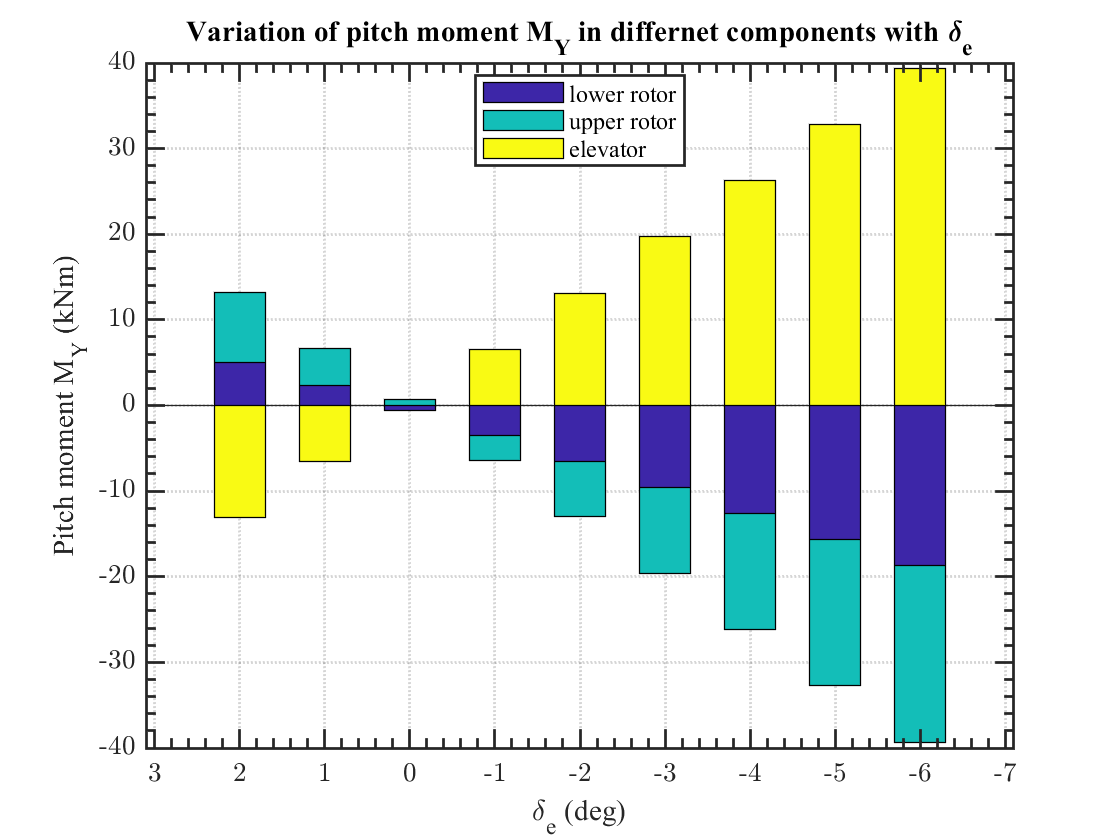



% M
fig = figure;
ax = axes(fig);

x = rad2deg(array_delta_e);
y1 = array_rotor1_M;
y2 = array_rotor2_M;
y3 = array_delta_e_M;

x = x(71:5:end);
y1 = y1(71:5:end)/1000;
y2 = y2(71:5:end)/1000;
y3 = y3(71:5:end)/1000;

Y = [y1,y2,y3];
b2 = bar(x,Y,'stacked','BarWidth',0.6,'FaceColor','flat');
set(gca,'XDir','reverse')
for k = 1:size(Y,2)
    b2(k).CData = k;
end

legend('lower rotor','upper rotor','elevator')
xlabel('\delta_e (deg)');ylabel('Pitch moment M_Y (kNm)');title('Variation of pitch moment M_Y in differnet components with \delta_e');


% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.2;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;
%ax.XLim = [-6,2];
%ax.YLim = [0,10];

leg = legend(ax);
leg.Location = 'best';

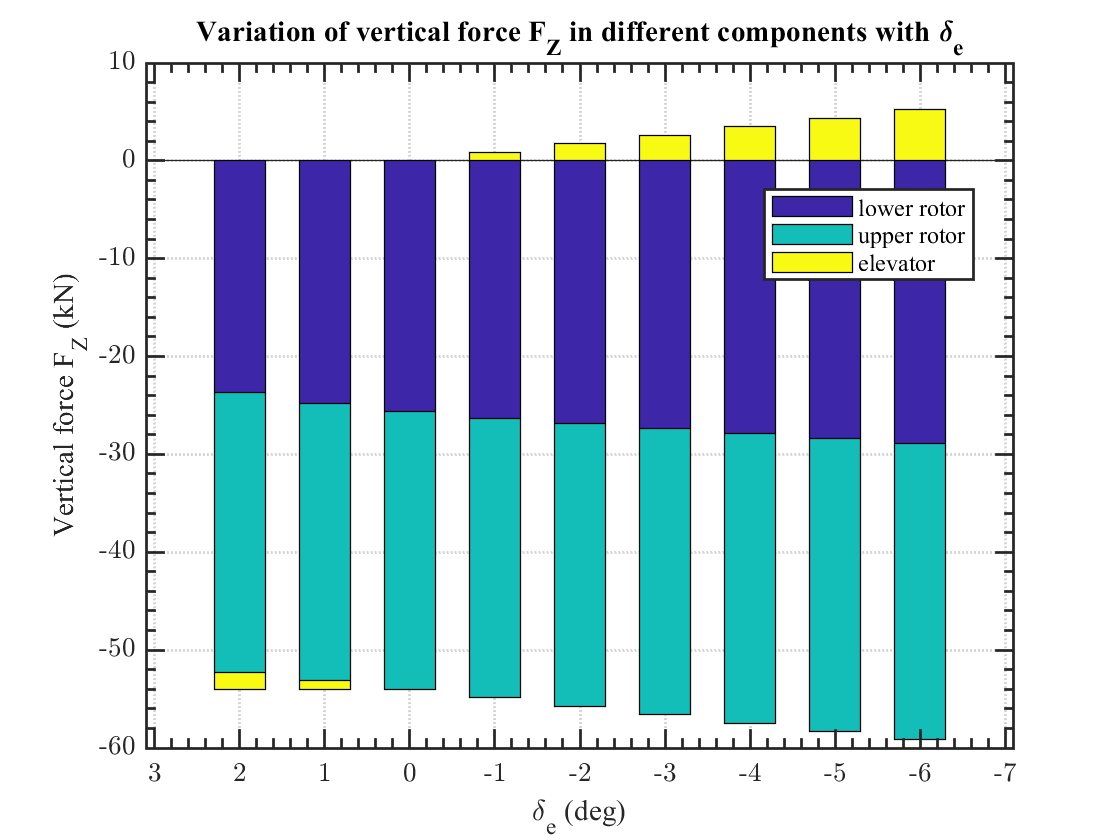



% Z
fig = figure;
ax = axes(fig);

x = rad2deg(array_delta_e);
y1 = array_rotor1_Z;
y2 = array_rotor2_Z;
y3 = array_delta_e_Z;

x = x(71:5:end);
y1 = y1(71:5:end)/1000;
y2 = y2(71:5:end)/1000;
y3 = y3(71:5:end)/1000;

Y = [y1,y2,y3];
b3 = bar(x,Y,'stacked','BarWidth',0.6,'FaceColor','flat');
set(gca,'XDir','reverse')
for k = 1:size(Y,2)
    b3(k).CData = k;
end

legend('lower rotor','upper rotor','elevator')
xlabel('\delta_e (deg)');ylabel('Vertical force F_Z (kN)');title('Variation of vertical force F_Z in different components with \delta_e');


% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.2;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;
%ax.XLim = [-6,2];
%ax.YLim = [0,10];

leg = legend(ax);
leg.Location = 'best';

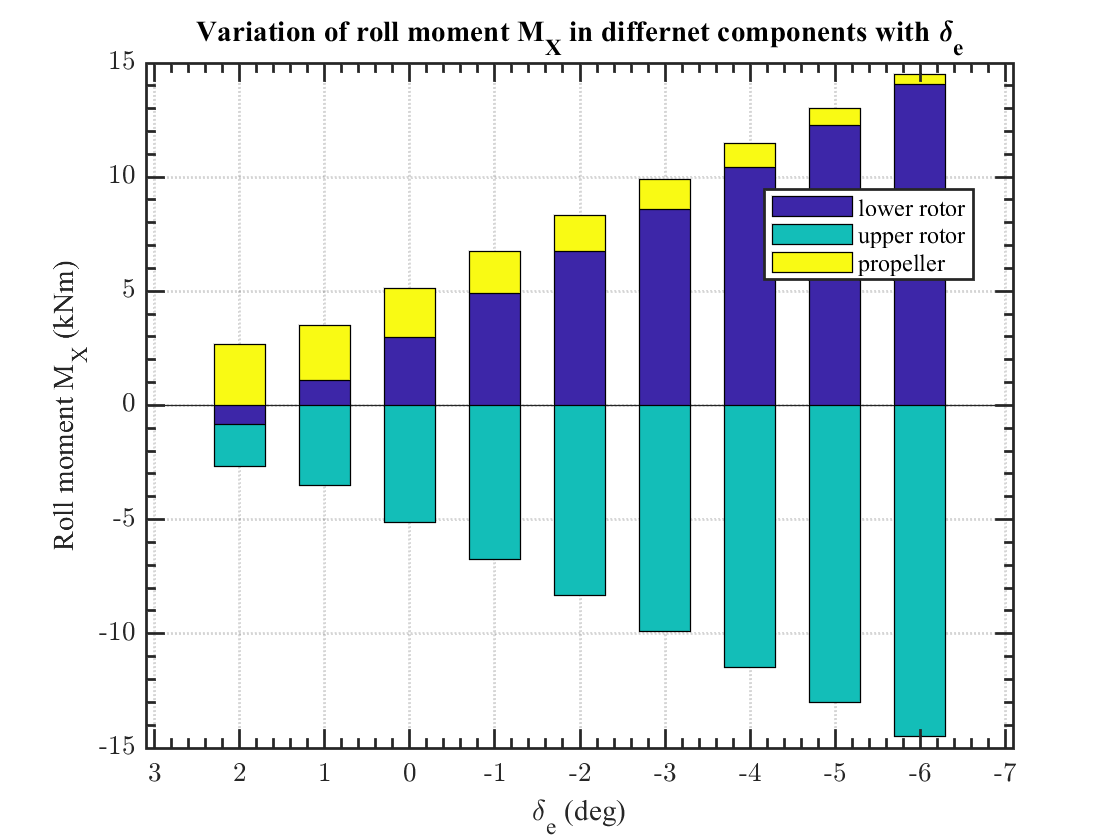


% L
fig = figure;
ax = axes(fig);

x = rad2deg(array_delta_e);
y1 = array_rotor1_L;
y2 = array_rotor2_L;
y3 = array_prop_L;

x = x(71:5:end);
y1 = y1(71:5:end)/1000;
y2 = y2(71:5:end)/1000;
y3 = y3(71:5:end)/1000;

Y = [y1,y2,y3];
b3 = bar(x,Y,'stacked','BarWidth',0.6,'FaceColor','flat');
set(gca,'XDir','reverse')
for k = 1:size(Y,2)
    b3(k).CData = k;
end

legend('lower rotor','upper rotor','propeller')
xlabel('\delta_e (deg)');ylabel('Roll moment M_X (kNm)');title('Variation of roll moment M_X in differnet components with \delta_e');


% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = ":";
ax.GridAlpha = 0.2;
ax.LineWidth = 1;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;
%ax.XLim = [-6,2];
%ax.YLim = [0,10];

leg = legend(ax);
leg.Location = 'best';

## 升降舵操纵功效

array_U = tabel_trim_redundant_prop.U;
array_dMddelta_e = zeros(size(array_U));
number_U = length(array_U);

for k = 1:number_U
    U = array_U(k);
    table_slice =   tabel_trim_redundant_prop(tabel_trim_redundant_prop.U == U,:);
    [x_trim,Rotorcraft,~] = calculate_from_trim_table(table_slice);
    derivatives = calculate_derivatives_primitive(Rotorcraft,x_trim);
    array_dMddelta_e(k) = derivatives.dMddelta_e;
end

array_eff_delta_e = array_dMddelta_e/26844;

## draw

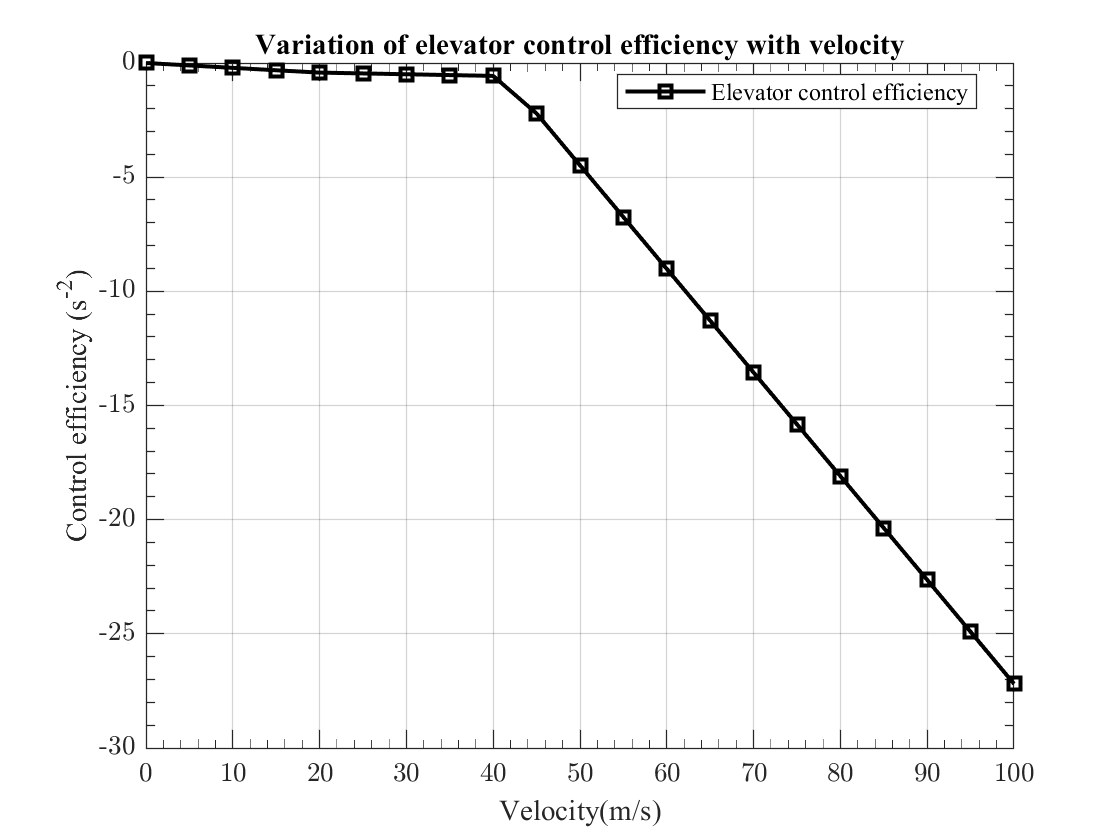

fig = figure;
ax = axes(fig);

x = array_U(1:5:end);
y = array_eff_delta_e(1:5:end);
h1 = plot(x,y,'k','LineWidth',1.5,'Marker','square');

legend('Elevator control efficiency');
xlabel('Velocity(m/s)');ylabel('Control efficiency (s^{-2})'); title('Variation of elevator control efficiency with velocity')

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = "-";
ax.GridAlpha = 0.2;
ax.LineWidth = 0.5;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;
%ax.YLim = [-5,5];

leg = legend(ax);
leg.Location = 'best';

## x:U,y:v_0

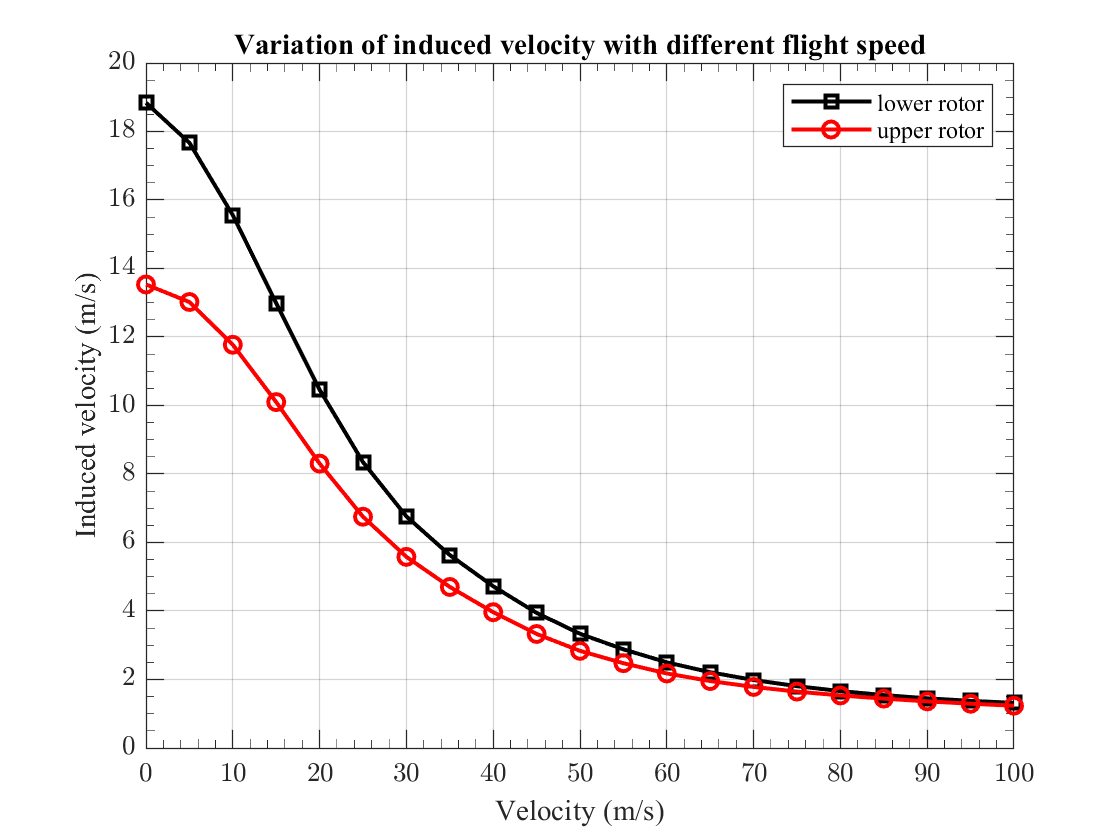

fig = figure;
ax = axes(fig);

x = tabel_trim_redundant_prop.U(1:5:end);
y = tabel_trim_redundant_prop.v_01(1:5:end);
plot(ax,x,y,'k','LineWidth',1.5,'Marker','square')
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = tabel_trim_redundant_prop.v_02(1:5:end);
plot(ax,x,y,'r','LineWidth',1.5,'Marker','o')
hold off

legend('lower rotor','upper rotor')
xlabel('Velocity (m/s)');ylabel('Induced velocity (m/s)'); title('Variation of induced velocity with different flight speed')

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = "-";
ax.GridAlpha = 0.2;
ax.LineWidth = 0.5;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;

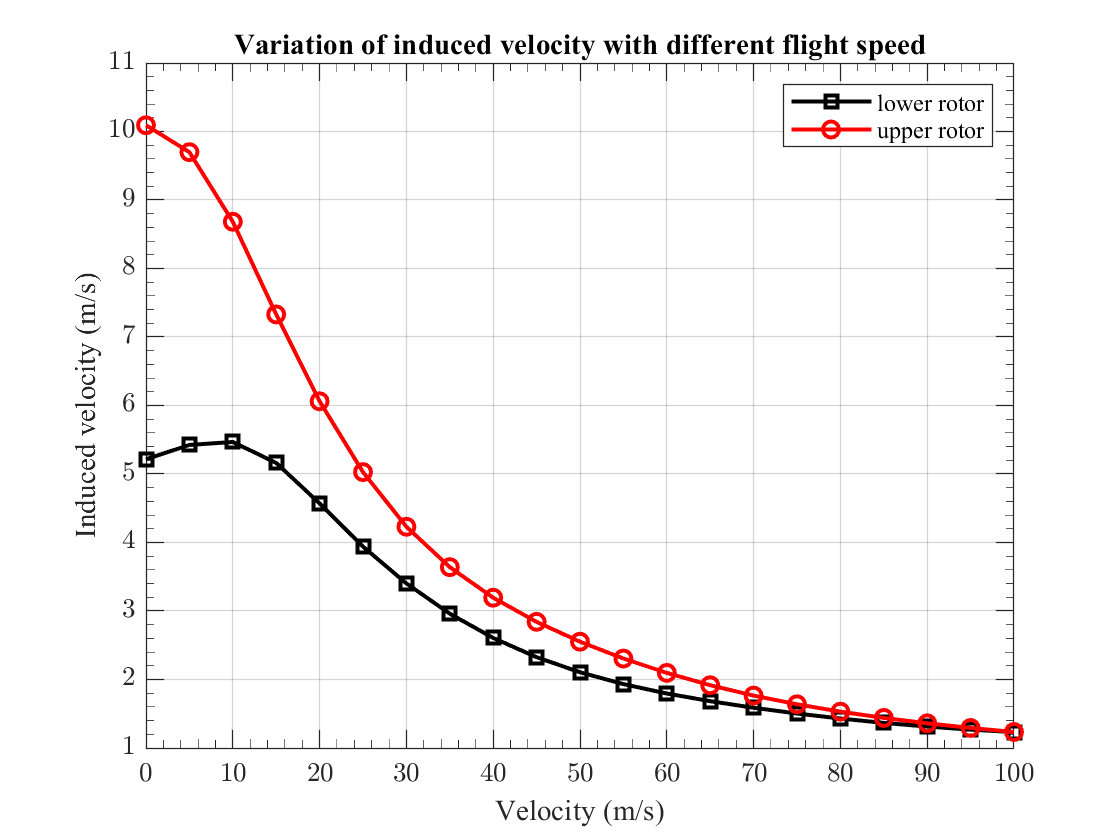


fig = figure;
ax = axes(fig);

x = tabel_trim_redundant_prop.U(1:5:end);
y = tabel_trim_redundant_prop.v_i1(1:5:end);
plot(ax,x,y,'k','LineWidth',1.5,'Marker','square')
hold on

x = tabel_trim_redundant_prop.U(1:5:end);
y = tabel_trim_redundant_prop.v_i2(1:5:end);
plot(ax,x,y,'r','LineWidth',1.5,'Marker','o')
hold off

legend('lower rotor','upper rotor')
xlabel('Velocity (m/s)');ylabel('Induced velocity (m/s)'); title('Variation of induced velocity with different flight speed')

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = "-";
ax.GridAlpha = 0.2;
ax.LineWidth = 0.5;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;

## x:U y:delta

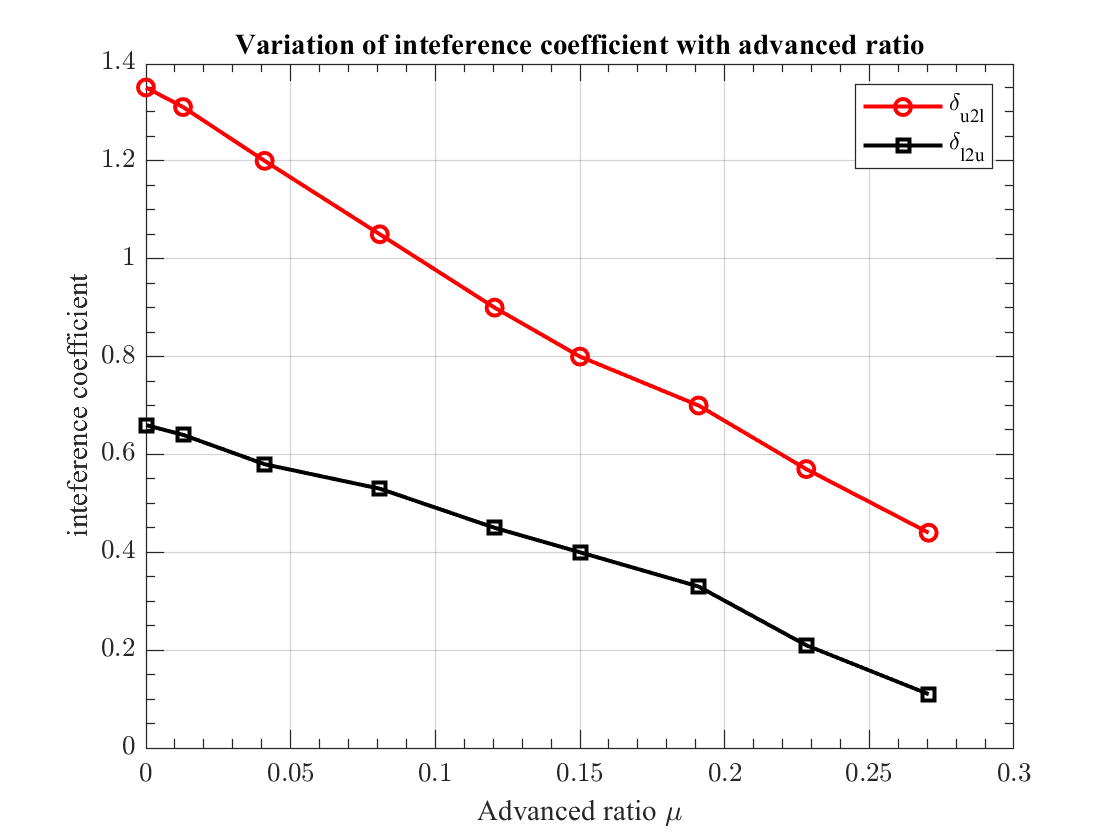

fig = figure;
ax = axes(fig);

array_mu = [0	0.0128	0.041	0.0808	0.1205	0.15	0.191	0.2282	0.2705];
array_delta_u2l = [1.35	1.31	1.2     1.05	0.9     0.8	0.7     0.57	0.44];
array_delta_l2u = [0.66	0.64	0.58	0.53	0.45	0.4	0.33	0.21	0.11];


plot(ax,array_mu,array_delta_u2l,'r','LineWidth',1.5,'Marker','o')
hold on

plot(ax,array_mu,array_delta_l2u,'k','LineWidth',1.5,'Marker','square')
hold off

legend('\delta_{u2l}','\delta_{l2u}')
xlabel('Advance ratio \mu'); ylabel('inteference coefficient'); title('Variation of flow interaction factor with advance ratio')

% adjust figure
fig.Color = [1.0, 1.0, 1.0]; % background color
ax.XGrid = 'on';
ax.YGrid = 'on';
ax.GridLineStyle = "-";
ax.GridAlpha = 0.2;
ax.LineWidth = 0.5;
ax.FontName = 'Times New Roman';
ax.FontSize = 10;
ax.TickLabelInterpreter = 'latex';
ax.XMinorTick = 'on';
ax.YMinorTick = 'on';
ax.TickLength(1) = 0.02;